clear
P = imread("C:\Users\Liushoukang\Desktop\VMIE\image\bridge.bmp");
Pr = Imreadforgary(P(:,:,1));
Pg = Imreadforgary(P(:,:,2));
Pb = Imreadforgary(P(:,:,3));
C =  imread("C:\Users\Liushoukang\Desktop\VMIE\image\Boat256.bmp");
Cr = Imreadforgary(C(:,:,1));
Cg = Imreadforgary(C(:,:,2));
Cb = Imreadforgary(C(:,:,3));
[CICSr,DIr,RIr]=VMIE(Pr,Cr);

历时 0.234131 秒。
历时 1.872410 秒。


[CICSg,DIg,RIg]=VMIE(Pg,Cg);

历时 0.238235 秒。
历时 1.638058 秒。


[CICSb,DIb,RIb]=VMIE(Pb,Cb);

历时 0.242869 秒。
历时 1.410236 秒。


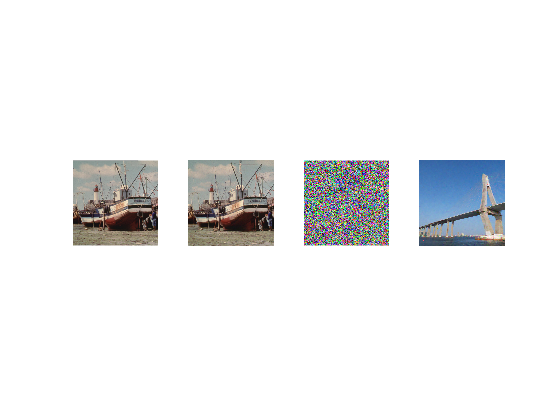

CICS(:,:,1)=uint8(CICSr);CICS(:,:,2)=uint8(CICSg);CICS(:,:,3)=uint8(CICSb);
DI(:,:,1)=DIr;DI(:,:,2)=DIg;DI(:,:,3)=DIb;
RI(:,:,1)=RIr;RI(:,:,2)=RIg;RI(:,:,3)=RIb;
subplot(141);imshow(uint8(C));
subplot(142);imshow(uint8(CICS));
subplot(143);imshow(uint8(DI));
subplot(144);imshow(uint8(RI));

psnr(uint8(RI),uint8(P))

ans = 30.0067

entropy(uint8(P))

ans = 7.4686

entropy(uint8(RI))

ans = 7.4528

HC = SUM(double(P(:,:,1)).*RI(:,:,1))/(sqrt(SUM(double(P(:,:,1)).^2))*sqrt(SUM(RI(:,:,1).^2)))

HC = 0.9965

ssim(uint8(CICS),uint8(C))

ans = 0.9940